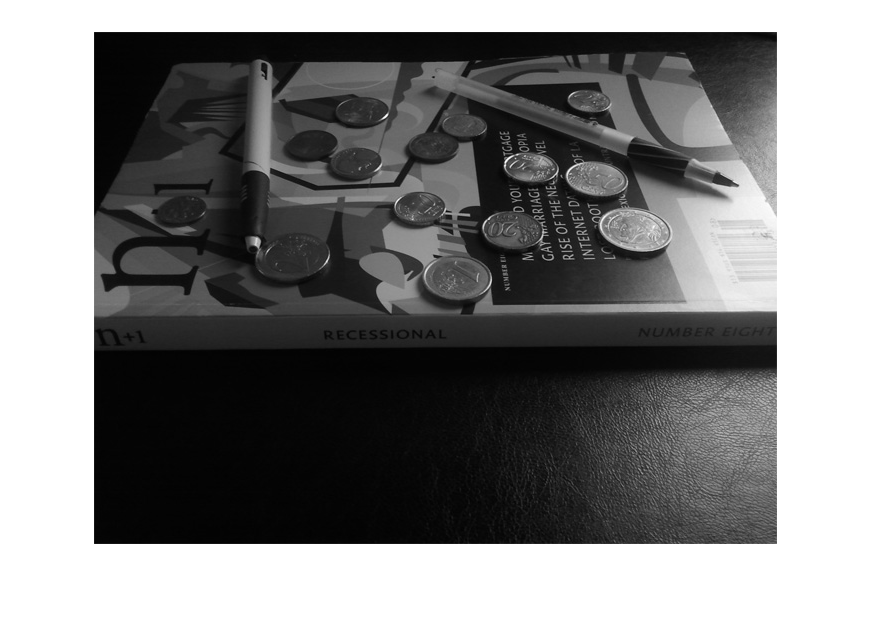

img = rgb2gray(imread("input/ps1-input3.png"));
imshow(img);

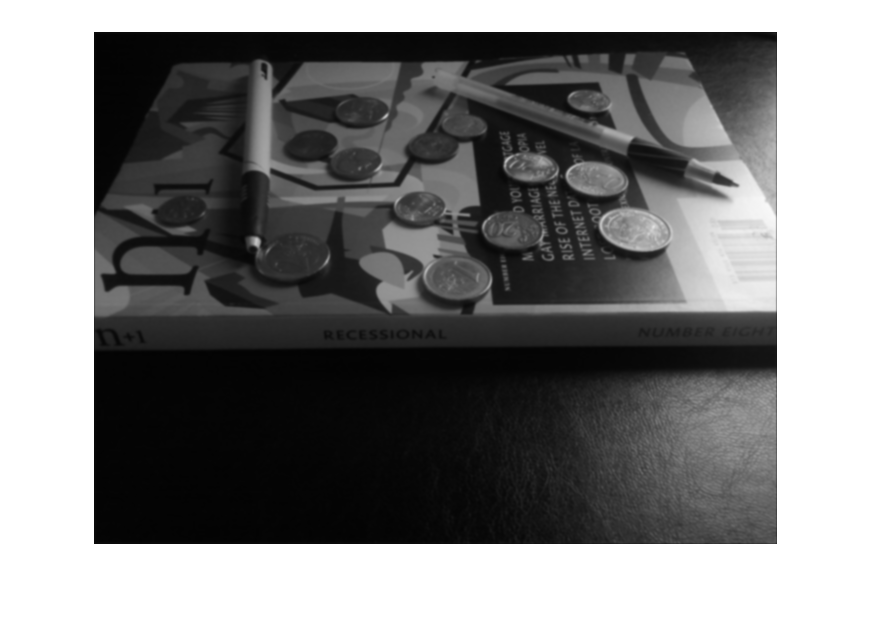

filter = fspecial('gaussian', 5, 1);
img_smooth = imfilter(img, filter);
imshow(img_smooth);

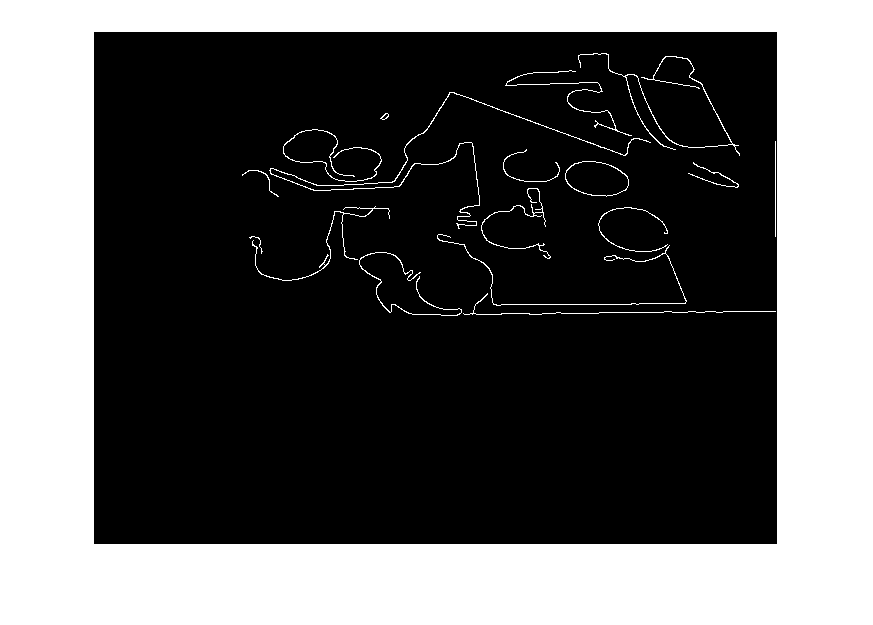


img_smooth_edges = edge(img_smooth,'Canny',[0.1 0.7] ,'both' );
imshow(img_smooth_edges);

img_edges = img_smooth_edges;


maxd = ceil(sqrt(size(img_edges,1)^2 + size(img_edges,2)^2));

deg_bins = linspace(-90,90,181);
d_bins = linspace(-maxd, maxd, maxd+1);
H = zeros(length(d_bins),length(deg_bins));
for r= 1: size(img_edges,1)
    for c= 1: size(img_edges,2)  
        if img_edges(r,c) == 1 
          for deg = -90 : 90
            x=c; y=r;
            angle = deg*pi/180;
            d = ceil(x*cos(angle)+y*sin(angle));
            deg_i = findbin(deg_bins, deg);
            d_i = findbin(d_bins, d);
            H(d_i,deg_i) = H(d_i,deg_i) +  1; 
          end
       end
    end
end

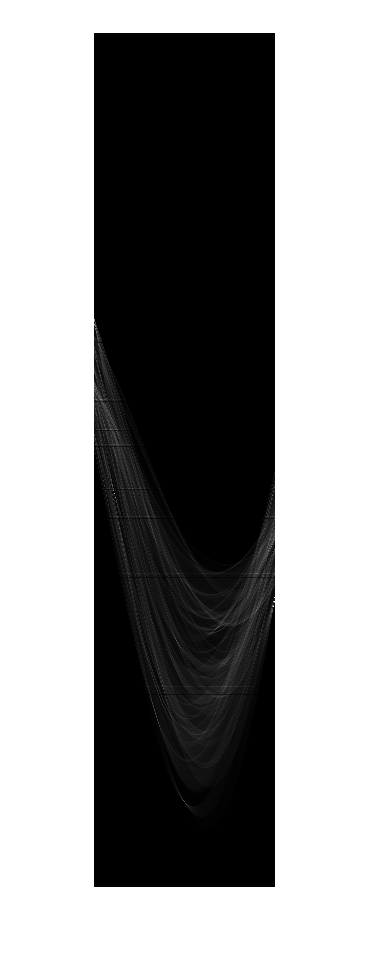


imshow(H,[]);

maxH = max(H(:))

maxH = 245

[maxrowyi , maxcolxi] = find(H >= 0.4*maxH & H<=maxH);

a = [maxcolxi,maxrowyi]

a =      1   287
     1   288
     1   289
     1   292
     1   354
     2   293
     2   294
     2   296
     3   300
     3   367


Using nearby parallel lines to identify pens

% A = [];
% for i = 1: size(a,1)
%     for j = i+1 : size(a,1)
%         if ( a(i,1) == a(j,1))
%             dist = abs(a(i,2) - a(j,2));
%             if(dist > 5 & dist < 20)
%               A = [A ; a(i,1), a(i,2) ; a(j,1), a(j,2)];
%             end
%         end
%     end
% end
% A = unique(A,'rows')
% a = A;

marks_image = insertMarker(H, a)

marks_image = marks_image(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

colormap gray;

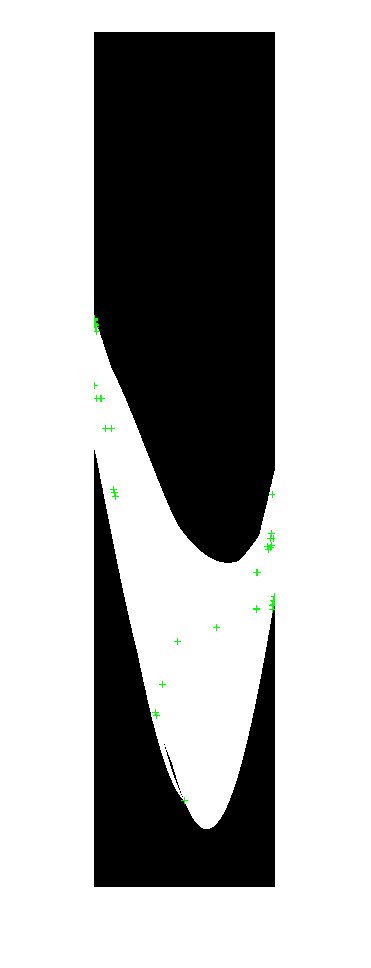

imshow(marks_image,[])

x = 1 : size(img_edges,2);
size(a,1)

ans = 43

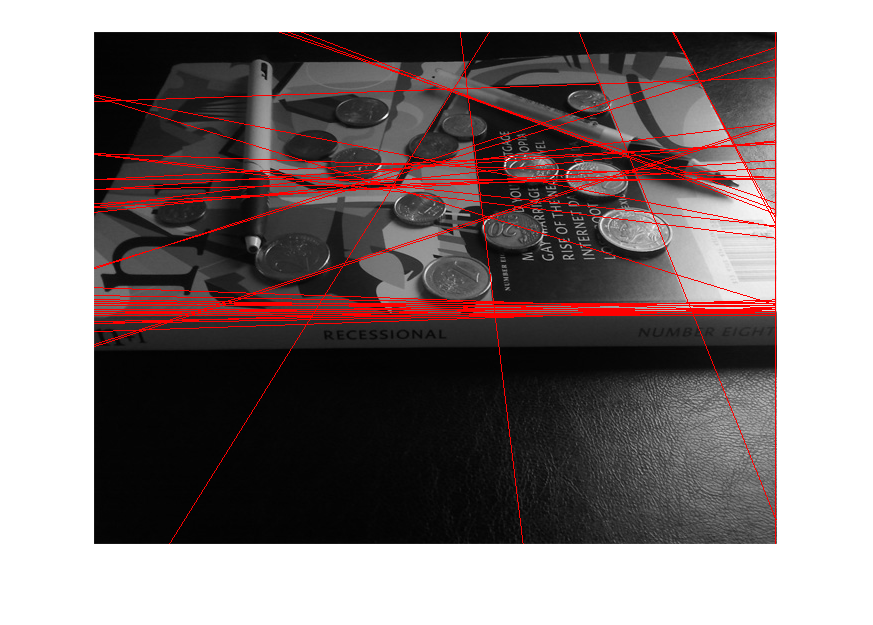

************line1


dvalue = -282

tvalue = -1.5708

other line


************line2


dvalue = -280

tvalue = -1.5708

other line


************line3


dvalue = -278

tvalue = -1.5708

other line


************line4


dvalue = -272

tvalue = -1.5708

other line


************line5


dvalue = -148

tvalue = -1.5708

other line


************line6


dvalue = -270

tvalue = -1.5533

other line


************line7


dvalue = -268

tvalue = -1.5533

other line


************line8


dvalue = -264

tvalue = -1.5533

other line


************line9


dvalue = -256

tvalue = -1.5359

other line


************line10


dvalue = -122

tvalue = -1.5359

other line


************line11


dvalue = -122

tvalue = -1.4661

other line


************line12


dvalue = -122

tvalue = -1.4486

other line


************line13


dvalue = -62

tvalue = -1.3788

other line


************line14


dvalue = -62

tvalue = -1.2741

other line


************line15


dvalue = 60.0000

tvalue = -1.2392

other line


************line16


dvalue = 66

tvalue = -1.2217

other line


************line17


dvalue = 74

tvalue = -1.2043

other line


************line18


dvalue = 506

tvalue = -0.5061

other line


************line19


dvalue = 512

tvalue = -0.4887

other line


************line20


dvalue = 450

tvalue = -0.3840

other line


************line21


dvalue = 364

tvalue = -0.1222

other line


************line22


dvalue = 682

tvalue = 0

inf line


************line23


dvalue = 336

tvalue = 0.5585

other line


************line24


dvalue = 226

tvalue = 1.2566

other line


************line25


dvalue = 298

tvalue = 1.2566

other line


************line26


dvalue = 300

tvalue = 1.2566

other line


************line27


dvalue = 226

tvalue = 1.2741

other line


************line28


dvalue = 174

tvalue = 1.4486

other line


************line29


dvalue = 180

tvalue = 1.4661

other line


************line30


dvalue = 158

tvalue = 1.5010

other line


************line31


dvalue = 176

tvalue = 1.5010

other line


************line32


dvalue = 148

tvalue = 1.5184

other line


************line33


dvalue = 172

tvalue = 1.5184

other line


************line34


dvalue = 70

tvalue = 1.5359

other line


************line35


dvalue = 292

tvalue = 1.5359

other line


************line36


dvalue = 300

tvalue = 1.5359

other line


************line37


dvalue = 158

tvalue = 1.5533

other line


************line38


dvalue = 282

tvalue = 1.5533

other line


************line39


dvalue = 290

tvalue = 1.5533

other line


************line40


dvalue = 292

tvalue = 1.5533

other line


************line41


dvalue = 274

tvalue = 1.5708

other line


************line42


dvalue = 282

tvalue = 1.5708

other line


************line43


dvalue = 284

tvalue = 1.5708

other line


imshow(img)
for i = 1:size(a,1)
    disp("************line"+i);
    dvalue = d_bins(1, a(i,2))
    tvalue = deg_bins(1,a(i,1))*pi/180
    if (tvalue == 0)
        disp("inf line");
        line([dvalue dvalue],[1 size(img_edges,2)], 'color', 'r')
    else
        disp("other line");
        line(x,(dvalue-x*cos(tvalue))/sin(tvalue), 'color','r')
    end
end